red=alexnet;
ls imagenes\*.jpg


file01.jpg  file03.jpg  file05.jpg  file07.jpg  file09.jpg  file11.jpg  
file02.jpg  file04.jpg  file06.jpg  file08.jpg  file10.jpg  file12.jpg  




ds_img=imageDatastore("imagenes\file*.jpg")

ds_img =   ImageDatastore with properties:

                       Files: {
                              'C:\Users\Pc\Documents\MATLAB\CLASS 09112022\imagenes\file01.jpg';
                              'C:\Users\Pc\Documents\MATLAB\CLASS 09112022\imagenes\file02.jpg';
                              'C:\Users\Pc\Documents\MATLAB\CLASS 09112022\imagenes\file03.jpg'
                               ... and 9 more
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
                     ReadFcn: @readDatastoreImage



nombres=ds_img.Files

nombres = 12×1 cell array
    {'C:\Users\Pc\Documents\MATLAB\CLASS 09112022\imagenes\file01.jpg'}
    {'C:\Users\Pc\Documents\MATLAB\CLASS 09112022\imagenes\file02.jpg'}
    {'C:\Users\Pc\Documents\MATLAB\CLASS 09112022\imagenes\file03.jpg'}
    {'C:\Users\Pc\Documents\MATLAB\CLASS 09112022\imagenes\file04.jpg'}
    {'C:\Users\Pc\Documents\MATLAB\CLASS 09112022\imagenes\file05.jpg'}
    {'C:\Users\Pc\Documents\MATLAB\CLASS 09112022\imagenes\file06.jpg'}
    {'C:\Users\Pc\Documents\MATLAB\CLASS 09112022\imagenes\file07.jpg'}
    {'C:\Users\Pc\Documents\MATLAB\CLASS 09112022\imagenes\file08.jpg'}
    {'C:\Users\Pc\Documents\MATLAB\CLASS 09112022\imagenes\file09.jpg'}
    {'C:\Users\Pc\Documents\MATLAB\CLASS 09112022\imagenes\file10.jpg'}
    {'C:\Users\Pc\Documents\MATLAB\CLASS 09112022\imagenes\file11.jpg'}
    {'C:\Users\Pc\Documents\MATLAB\CLASS 09112022\imagenes\file12.jpg'}



img=readimage(ds_img,7)

img = 227×227×3 uint8 array
img(:,:,1) =

   191   180   169   191   190   199   200   192   169   166   175   169   173   172   153   156   161   175   176   170   167   166   177   192   188   177   186   162   168   185   180   162   171   191   151   131   153   163   155   195   190   136    70    46    44    52    97   139   166   177   168   146   155   149    88    41    42    29    67   167   211   209   204   213   189   195   186   165   176   196   175   149   118   137   173   158   155   165   161   142   152   160   159   164   163   164   174   166   135   132   143   160   156   164   178   154   141   136   152   152   130   142   141    89    61    58    65    75    92   146   181   173   169   147   154   151   143   119   113   141   144   136   148   158   147   128   143   145   162   178   206   194   187   173   183   165   147   147   151   182   192   185   195   184   185   181   185   182   171   168   174   178   179   174   159   162   158   186   195   2

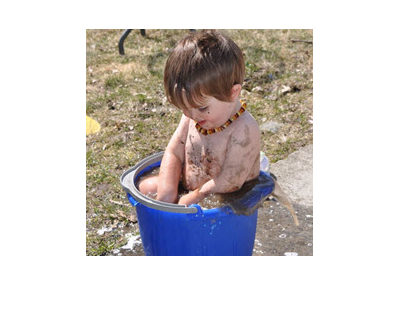

imshow(img)

pred=classify(red,ds_img)

pred = 12×1 categorical array
     seashore 
     Shetland sheepdog 
     bakery 
     breakwater 
     hotdog 
     lakeside 
     bucket 
     studio couch 
     Japanese spaniel 
     cardigan 
     paddle 
     sandbar 
